# Plant

clear
% Aerodynamic damping during rapid flight maneuvers in the fruit fly Drosophila
% B. Cheng, S. N. Fry, Q. Huang, X. Deng
% Journal of Experimental Biology 2010 213: 602-612; doi: 10.1242/jeb.038778
Cu = 21e-12;
I = 4.971e-12;
G_plant = tf(Cu,[I 0]) %Torque to Velocity

G_plant =
 
    2.1e-11
  -----------
  4.971e-12 s
 
Continuous-time transfer function.



# Globals

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

# Signal 1: Chirp

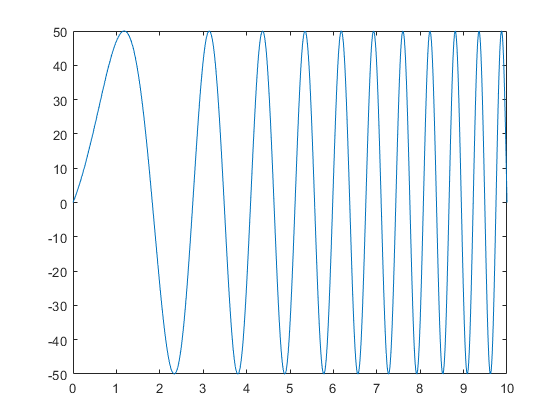

scale = 50;
f_start = 0.1;
f_end = 2;
chirps = scale*chirp(t,f_start,t(end),f_end,'linear',-90);
figure
plot(t,chirps)

# Signal 2: SoS

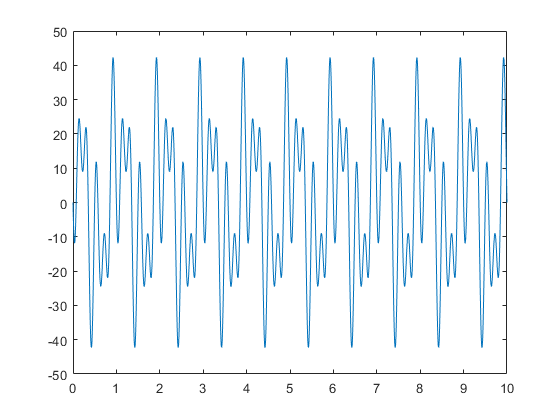

f = [2*pi 6*pi 10*pi];
p = [pi/6 pi/2 pi/3];
ssscale = scale/3;

%Make a higher resolution t vector for finding zero crossing
highdelta = 0.0000001;
t_temp = 0:highdelta:t_final;
for i = 1:size(t_temp,2)
    sostemp(i) = ssscale*(sin(f(1)*t_temp(i)+p(1))+sin(f(2)*t_temp(i)+p(2))+sin(f(3)*t_temp(i)+p(3)));
end
[zeroind,zerodist] = zerocross(sostemp);

t_cross = t_temp(zeroind);

%Time shifted SoS for initial value close to zero
for i = 1:size(t,2)
    sos(i) = ssscale*(sin(f(1)*(t(i)+t_cross)+p(1))+sin(f(2)*(t(i)+t_cross)+p(2))+sin(f(3)*(t(i)+t_cross)+p(3)));
end

figure
plot(t,sos)

# Model

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize,'FastRestart','on')
save_system(simName)

# Sweep across switching threshold

%Input
V_in = [t' sos'];

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper
K_P = 6; %Proportional Gain
K_I = .05; %Integral Gain of smooth system


switch_threshbig = 0.01:0.01:5; %Integrated error threshold for switching between smooth/saccadic
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    soserrorsingle(i) = sum(abs(sos'-out.V_out));
end

figure
plot(switch_threshbig,normalize(soserrorsingle,'range'))
hold on

%Input
V_in = [t' chirps'];
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    chirpserrorsingle(i) = sum(abs(chirps'-out.V_out));
end

plot(switch_threshbig,normalize(chirpserrorsingle,'range'))

K_P = 3; %Proportional Gain

V_in = [t' sos'];
switch_threshbig = 0.01:0.01:5; %Integrated error threshold for switching between smooth/saccadic
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    soserrorsingle(i) = sum(abs(sos'-out.V_out));
end

plot(switch_threshbig,normalize(soserrorsingle,'range'))

%Input
V_in = [t' chirps'];
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    chirpserrorsingle(i) = sum(abs(chirps'-out.V_out));
end

plot(switch_threshbig,normalize(chirpserrorsingle,'range'))
ylabel('Normalized Error')
xlabel('Switching Threshold')
legend('SoS Error, K_p = 6','Chirp Error, K_p = 6','SoS Error, K_p = 3','Chirp Error, K_p = 3')

# Optimal Point Gain Sweep

Prange = .1:.1:6;
Irange = .1:.1:6;
switchrange = 0.01:0.01:5;

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper

%Input
V_in = [t' sos'];


minswitch = zeros(size(Prange,2)*size(Irange,2),3);
error = zeros(1,size(switchrange,2));
iter=1;
for i = 1:size(Prange,2)
    for j = 1:size(Irange,2)
        tic
        K_P = Prange(i);
        K_I = Irange(j);
        for k = 1:size(switchrange,2)
            switch_thresh = switchrange(k);
            out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
            error(k) = sum(abs(sos'-out.V_out));
        end
        [minerror,index] = min(error);
        minswitch(iter,:) = [K_P K_I switchrange(index)];
        toc
        iter=iter+1;
    end  
end

Elapsed time is 42.051945 seconds.
Elapsed time is 45.020104 seconds.
Elapsed time is 42.838453 seconds.
Elapsed time is 41.469194 seconds.
Elapsed time is 41.503563 seconds.
Elapsed time is 41.348723 seconds.
Elapsed time is 41.595566 seconds.
Elapsed time is 41.519520 seconds.
Elapsed time is 40.957751 seconds.
Elapsed time is 40.671701 seconds.
Elapsed time is 40.640333 seconds.
Elapsed time is 40.737988 seconds.
Elapsed time is 40.728692 seconds.
Elapsed time is 40.784579 seconds.
Elapsed time is 40.755142 seconds.
Elapsed time is 40.774078 seconds.
Elapsed time is 40.754798 seconds.
Elapsed time is 40.735875 seconds.
Elapsed time is 40.778011 seconds.
Elapsed time is 40.802064 seconds.
Elapsed time is 40.786530 seconds.
Elapsed time is 40.752801 seconds.
Elapsed time is 40.795306 seconds.
Elapsed time is 40.712944 seconds.
Elapsed time is 40.753390 seconds.
Elapsed time is 40.813684 seconds.
Elapsed time is 40.861900 seconds.
Elapsed time is 40.715008 seconds.
Elapsed time is 40.8


filename1 = strcat('ch','_',num2str(scale),'_',num2str(f_start),'_',num2str(f_end),'_');
filename2 = strcat('ssf','_',num2str(f(1)),'_',num2str(f(2)),'_',num2str(f(3)),'_');
filename3 = strcat('ssp','_',num2str(p(1)),'_',num2str(p(2)),'_',num2str(p(3)),'_');
filename4 = strcat('kp','_',num2str(Kp(1)),'_',num2str(Kp(2)-Kp(1)),'_',num2str(Kp(end)),'_');
filename5 = strcat('ki','_',num2str(Ki(1)),'_',num2str(Ki(2)-Ki(1)),'_',num2str(Ki(end)),'_');
filename6 = strcat('sw','_',num2str(switchrange(1)),'_',num2str(switchrange(2)-switchrange(1)),'_',num2str(switchrange(end)));
filename = strcat(filename1,filename2,filename3,filename4,filename5,filename6,'.mat')
save(filename,'minswitch','chirps','sos','scale')

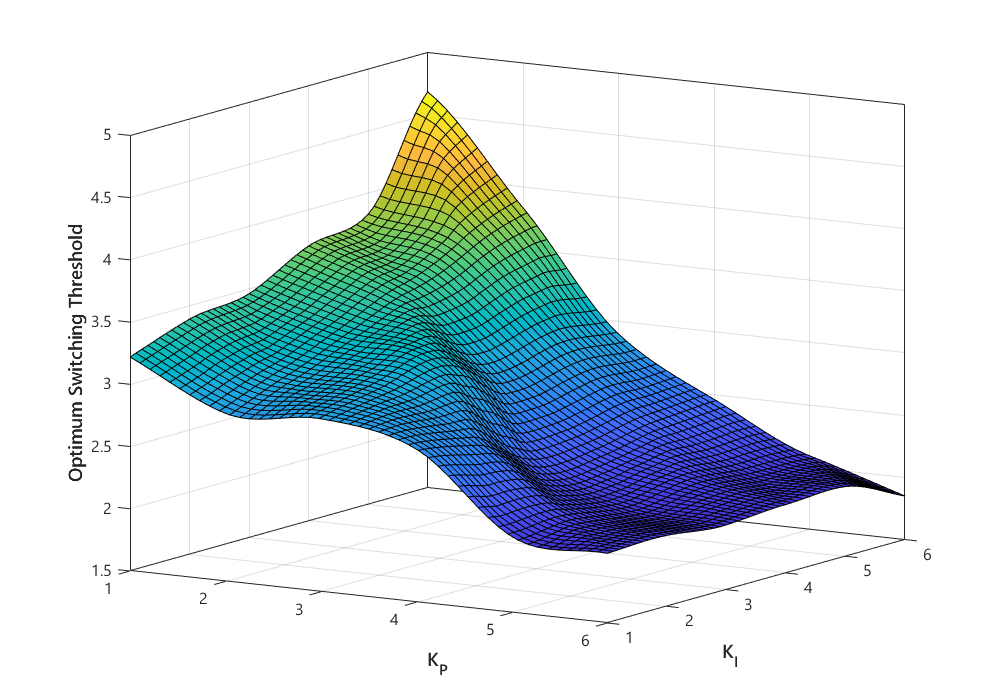

sf = fit([minswitch(:,1), minswitch(:,2)],minswitch(:,3),'cubicinterp');
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
set(gcf, 'Color', 'w');
plot(sf)% [stabletip(:,1), stabletip(:,2)],stabletip(:,3))
ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Optimum Switching Threshold','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-30,25)